clc;
clear all;
close all;

%Paremeters
fontsize=15;%for plotting

initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2025
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.49.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)...
***Local changes to submodules have been stashed. See https://git-scm.com/docs/git-stash.
Entering 'binary'
No local changes to save
Entering 'external/analysis/Cn

%This lists all the versions of functions named initCobraToolbox in your matlab installation, after the current path, the version used is the first in this list.
which -all initCobraToolbox


#### Placing the folder with the mat file and loading the model

% Specify the MAT file you're looking for
matFileName = 'model_aux.mat';
%placing the project folder with the mat file
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\semeco_explained\code


%place the current Matlab folder with the project files
cd(fileparts(which(matFileName)));
%load the model
load(matFileName);


#### Inspecting the model

% default constraints on the model
printConstraints(model_aux,-1000,1000)

    Forward_Reaction, non-0 bound                 Name                  lb    ub                                           equation                                       
    _____________________________    _______________________________    __    __    ______________________________________________________________________________________

            {'AUXOSATPM'}            {'ATP maintenance requirement'}    1     1     {'AUXOSCatp_u[u] + AUXOSCh2o_u[u]  -> AUXOSCadp_u[u] + AUXOSCh_u[u] + AUXOSCpi_u[u] '}
            {'PROTSATPM'}            {'ATP maintenance requirement'}    1     1     {'PROTSCatp[x] + PROTSCh2o[x]  -> PROTSCadp[x] + PROTSCh[x] + PROTSCpi[x] '          }




% By convention, the number of rows in S is equal to the 
% number of metabolites, and number of columns is equal to the 
% number of reactions:
[nMets,nRxns] = size(model_aux.S);
disp(['Number of metabolites: ',num2str(nMets)])

Number of metabolites: 2290


disp(['Number of reactions: ',num2str(nRxns)])

Number of reactions: 2991


**Visualization of the S matrix**

**Description:** The Yeast cell model S matrix can be visualized by using the spy command in Matlab. This command will represent all non-zero entries in S with a dot

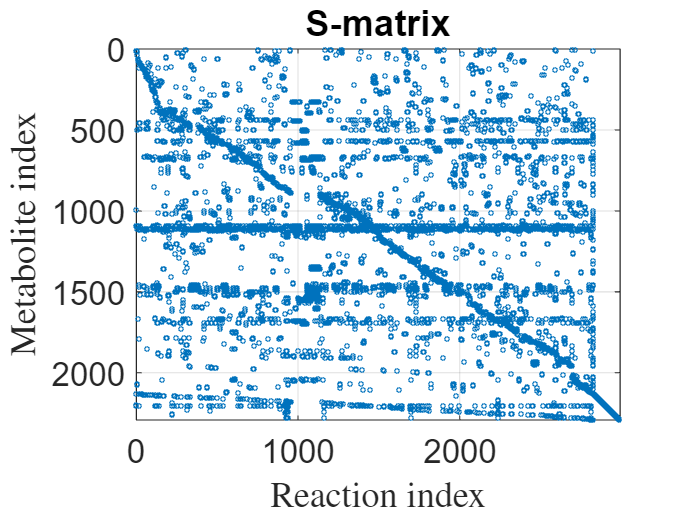

figure;
spy(model_aux.S,'o',2); grid on;
xlabel('Reaction index','Interpreter','latex');
ylabel('Metabolite index','Interpreter','latex');
title('S-matrix')
set(gca,'FontSize',fontsize);

**Number of reactions the metabolites occur in**

**Description:** The S matrix can be converted into a binary matrix (Sbin), by replacing all non-zero elements in S with a ‘1’ in Sbin. Then, all ones in each row of the Sbin can be summed to determine the number of reactions a metabolite occurs in.  The full code to binarize the S matrix and calculate and plot metabolite connectivity is:

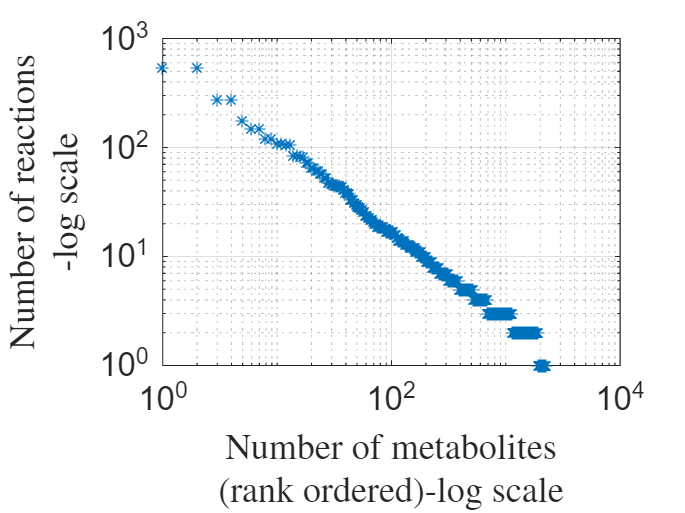

Sbin = zeros(size(model_aux.S));
Sbin(find(model_aux.S))=1;

for i = 1 : length(model_aux.mets)
    metConnectivity(i,1) = sum(Sbin(i,:));
end

loglog(sort(metConnectivity,'descend'),'*');grid on;
xlabel({'Number of metabolites','(rank ordered)-log scale'},'Interpreter','latex');
ylabel({'Number of reactions','-log scale'},'Interpreter','latex');
set(gca,'FontSize',fontsize);

**Reaction participation **

**Description**: Reaction participation refers to the number of metabolites per reaction. To determine reaction participation for every reaction, the number of non-zero elements per column in Sbin is counted. In the Yeast cell model, there are on average 4.3 metabolites per reaction (mean(rxnParticipation)). 

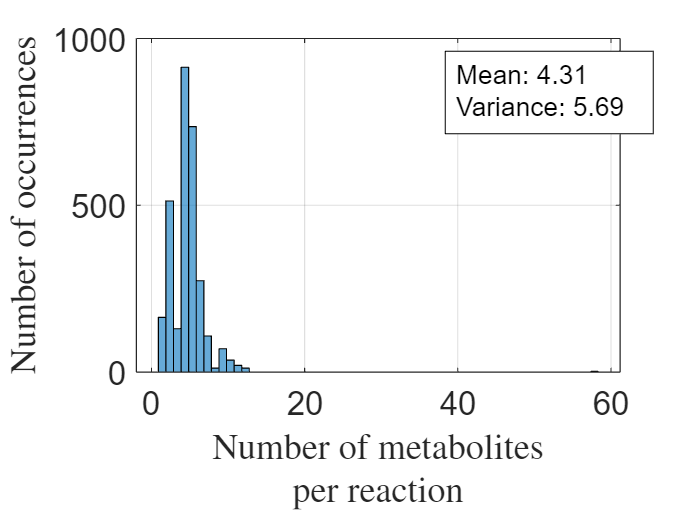

for i = 1 : length(model_aux.rxns)
    rxnParticipation(i,1) = sum(Sbin(:,i));
end

figure;
histogram(rxnParticipation,max(unique(rxnParticipation))); grid on;
xlabel({'Number of metabolites','per reaction'},'Interpreter','latex');
ylabel('Number of occurrences','Interpreter','latex');
% Calculate statistics
m = mean(rxnParticipation);
v = var(rxnParticipation);

% Create the text string with the mean and variance
statsStr = sprintf('Mean: %.2f\nVariance: %.2f', m, v);

% Add a textbox annotation in normalized coordinates.
% [x y width height] where (x,y) is the lower-left corner in normalized units.
annotation('textbox', [0.65, 0.75, 0.25, 0.15], 'String', statsStr, ...
    'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'k', 'FontSize', 12);
set(gca,'FontSize',fontsize);

How many metabolites are co-occurring in two reactions? 

To determine the number of metabolites common to two reactions, one needs to calculate the compound adjacency matrix (Acomp); Acomp = Sbin * SbinT. This multiplication leads to a square matrix of size m*m, where m is the number of metabolites in the network.

% Acomp = Sbin*Sbin';

The diagonal elements correspond to the metabolite connectivity (computed above), and can be extracted as follows:

% metConnectivity = diag(Acomp);

The off-diagonal elements correspond to the number of reactions two metabolites are co-occurring in. The cofactor pair nad[c] and nadh[c] occurs in 12 reactions together. Moreover, the connectivity of both metabolites is 12, thus, they only occur as pairs in the core E. coli model.

Is there any correlation between reaction essentiality and metabolite connectivity19?

One way to address this question is to delete all reactions in the network that are associated with a metabolite and ask if the network can still produce biomass. To find all reactions associated with a metabolite, one has to just scan through the corresponding rows in the S matrix.  Then the associated genes can be knocked out, and FBA can be used to predict if growth is possible.  The full code to perform these calculations and plot the results is:

% 
% growthDel = zeros(length(model_aux.mets),1);
% for i = 1 : length(model_aux.mets)
%     rxnID = find(model_aux.S(i,:));
%     for j = 1 : length(rxnID)
%         modelDel = deleteModelRxn(model_aux,model_aux.rxns(rxnID(j)));
%         FBAsolutionDel = optimizeCbModel(modelDel);
%         if FBAsolutionDel.f <= 1e-6
%             growthDel(i,1) = growthDel(i,1) + 1;
%         end
%     end
% end
% 
% lethalityFraction = growthDel./metConnectivity;
% semilogx(metConnectivity,lethalityFraction,'*')
% xlabel('metabolite connectivity - log scale');
% ylabel('average lethality fraction');


Logical indexing - the most powerful way to access any form of array. Find all the reactions which produce or consume oxygen

% model.rxns{model_aux.S(57,:)~=0}

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end